# Islanded Operation of Remote Microgrid Using Droop Controllers with Multiple Fidelity Levels

This example shows islanded operation of a remote microgrid modeled in Simulink® using Simscape™ Electrical™ components. This example demonstrates the simplest grid-forming controller with droop control.

## **Remote Microgrid Model**

A remote microgrid is often used to serve electric loads in locations without a connection to the main grid. Because the main grid is not available to balance load changes, controlling such a low-inertia microgrid is challenging.

The microgrid in this example consists of two inverter subsystems connected to two different points of common coupling (PCC) buses. The microgrid originally reaches power balance with the fixed loads while a switchable load also connects to the microgrid. A microgrid typically has a preplanned load shedding strategy to reach balanced operations. In a remote microgrid, instant load shedding is difficult to implement. In this example, there is no high-level energy management system, so the microgrid frequency and voltage are kept around their nominal values (60 Hz and 380 Vrms, respectively) using droop control.

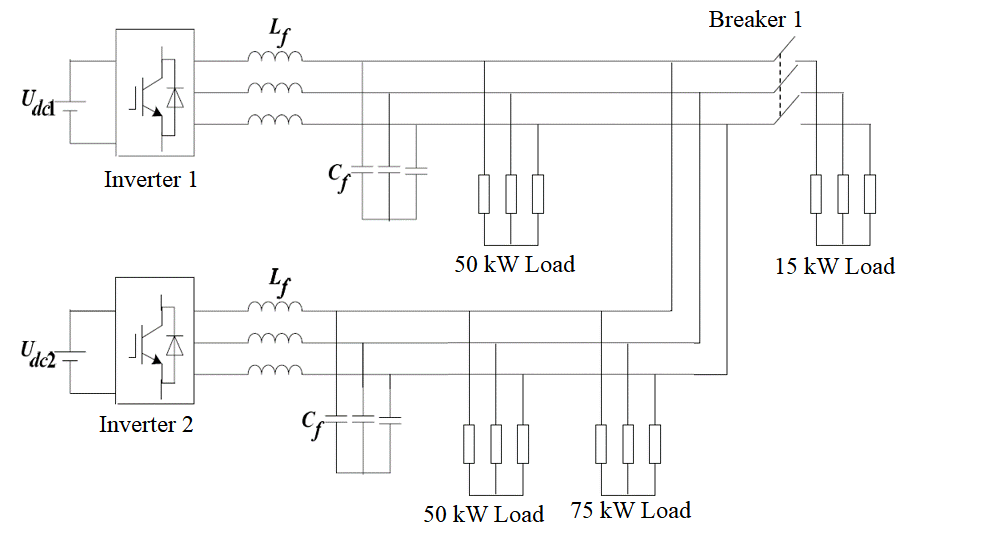

In this microgrid diagram, each inverter subsystem interfaces an ideal DC source to represent the DC link of a typical renewable energy generation system, such as a photovoltaic array, wind turbine, or battery energy storage system. Each subsystem includes a droop controller to calculate the d-axis and q-axis reference voltages. The voltage controller regulates voltages by generating the switching sequences feeding to the inverter. The loads originally connected consume a total of 175 kW AC power with a power factor of 0.95.

## **Droop Control**

The droop P/F is set to 2.5%, meaning that microgrid frequency is allowed to vary 1.5 Hz with 1 p.u. change of real power injected from an inverter. The droop Q/V is also set to 2.5%, meaning that the microgrid voltage at each PCC bus is allowed to vary over a range of 9.5 Vrms around the nominal 380 Vrms with 1 p.u. change of reactive power.

## **Microgrid Model**

Open the model.

mdl = 'scd3busMicrogridDroopControlFidelityLevels';
open_system(mdl)

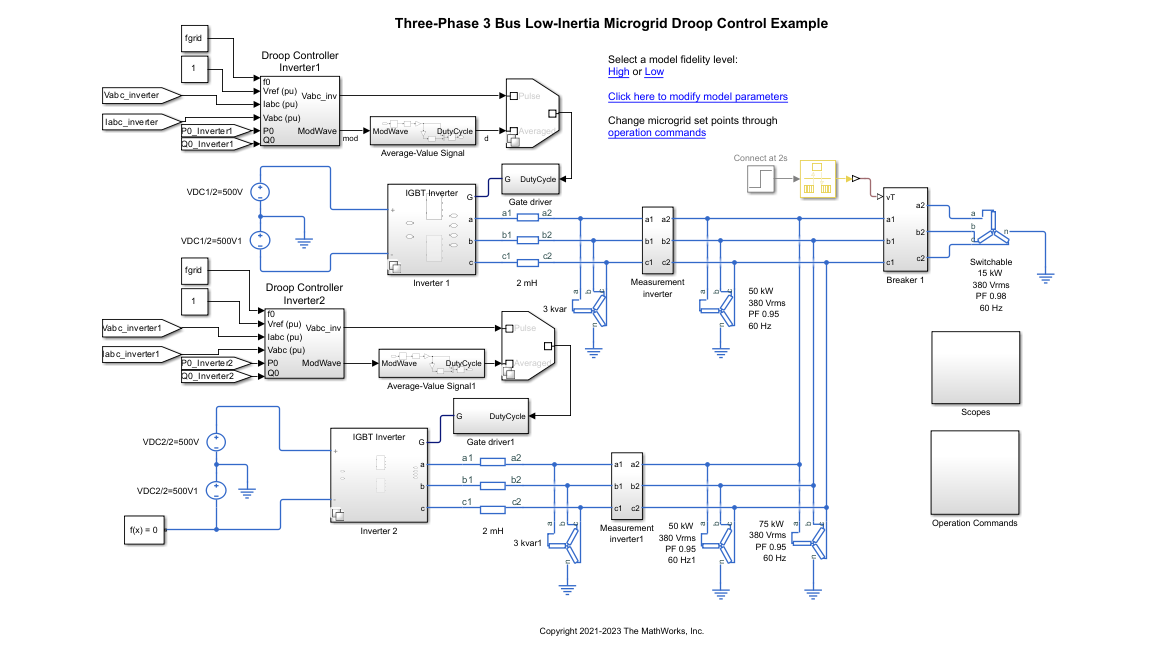

The microgrid is connected to two separate DC sources, each with a nominal voltage of 1000 V. There is a total of 175 kW load in the microgrid at the beginning of simulation. At 2 seconds, a load consuming 15 kW real power with a power factor of 0.98 is connected into the microgrid through a breaker, `Breaker 1`. The microgrid's operation, including the real and apparent power consumption of both inverters, is scheduled using a scenario loaded into a Signal Editor block inside the `Operation Commands` subsystem.

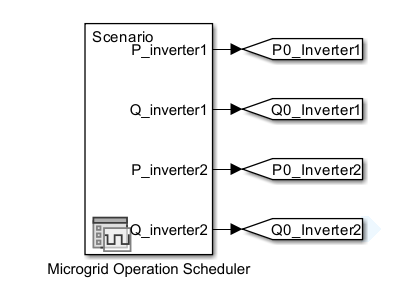

### **Model Fidelity Levels**

You can simulate the inverter switching behavior in low or high fidelity, depending on your needs. The active variant in the `Inverter` subsystems determines the fidelity level.

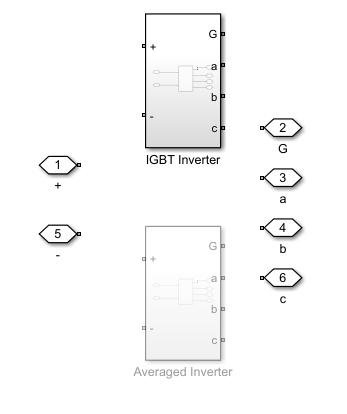

### **High-Fidelity Mode**

In high-fidelity mode, a PWM Generator block creates a switch gate signal, `g`. This signal is then fed to the gate input of the inverter, **G**.

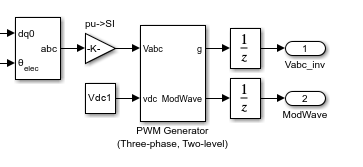

The high-fidelity mode models and simulates all switches within the inverter individually. By default, the switches are IGBT models. You can change the switch model using the **Switching device** parameter in the Converter (Three-Phase) block.

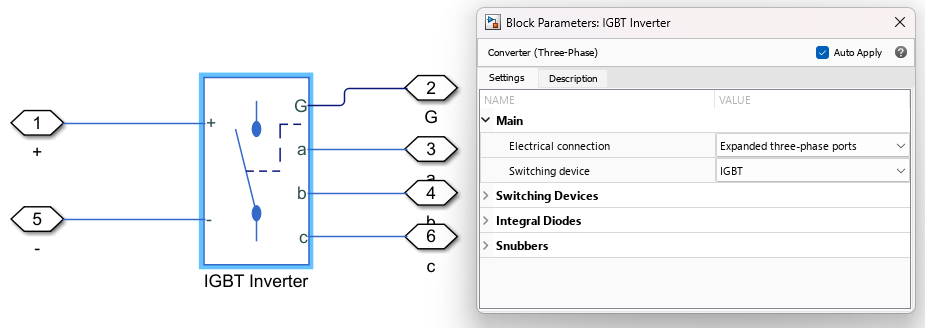

This level of switch simulation represents the inverter behavior in great detail and captures any small changes in the output voltage and frequency. However, because the high-fidelity mode models the behavior of each individual switch within the inverter, it results in slower simulation times. For this reason, the high-fidelity model is best used when you are interested in closely analyzing system response characteristics, such as the voltage or frequency ripple, and simulation time is a lower priority.

### Low-Fidelity Mode

In low-fidelity mode, the **Switching device** parameter of the Converter (Three-Phase) block is set to `Averaged Switch`, which uses an averaged PWM inverter model instead of fully modeling each individual switch.

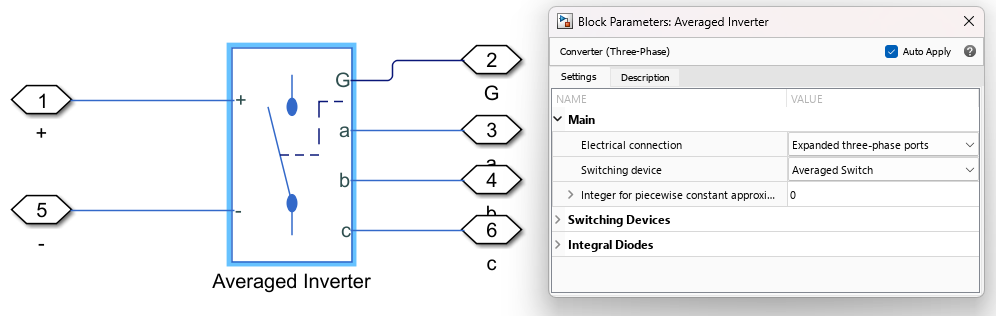

The averaged PWM model works by using the modulation waveform that is output by the PWM Generator (Three-phase, Two-level) block and converting this modulation waveform from the range [–1,1] to a duty cycle signal in the range [0,1]. When the low-fidelity mode is active, this duty cycle signal replaces the switch signal as the inverter gate input.

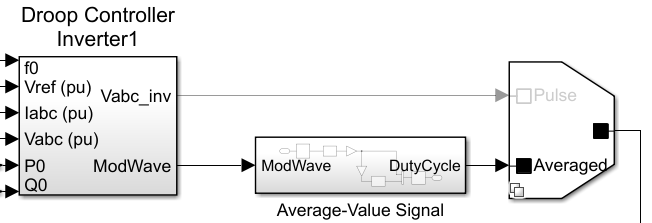

The model performs the duty cycle conversion in the `Average-Value Signal` subsystem.

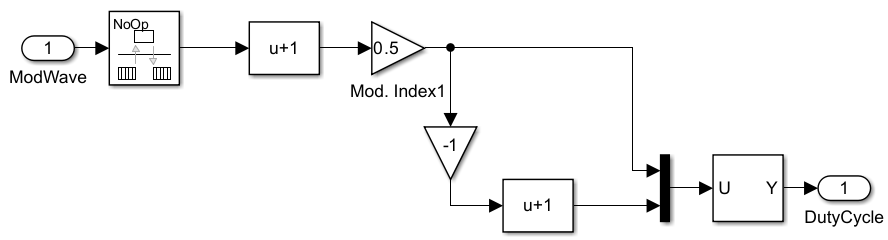

Because the switches are not modeled in this mode, simulation steps are permitted to be larger than the switching period, resulting in faster simulations. However, this also causes some converter phenomena such as voltage and frequency ripple to not be fully captured. Since the low-fidelity model simulates more quickly but does not fully represent all inverter behavior, it is best used in situations where you would like to run simulations in quick succession and are primarily interested in the system's high-level operation, such as when trying out different controller design iterations.

## **Simulation**

To change the active fidelity level, in the Simulink model, under **Select a model fidelity level**, click **Low** or **High**. The model is set to high-fidelity mode by default, so first simulate the model in this mode. You can change the model parameters using the `scd3busMicrogridDroopControlDataFidelityLevels.m` script provided with this example. Additionally, to change the inverter real and apparent power setpoints P and Q, respectively, edit the active scenario in the Signal Editor block.

To observe the simulation results, open the inverter frequency and voltage scopes.

open_system([mdl,'/Scopes/Inverter Freq']);
open_system([mdl,'/Scopes/Voltage']);

### High Fidelity Simulation

First, perform a model update.

set_param(mdl,'SimulationCommand','update');

Simulate and time the model in high-fidelity mode (this may take a few minutes, depending on your system).

tic;
sim(mdl);
highFidelitySimTime = toc;
highFidelityLogs = logsout;
fprintf("High fidelity simulation took %.2f seconds\n", highFidelitySimTime)

High fidelity simulation took 394.30 seconds


After the abrupt load increase at 2 seconds, the microgrid maintains its frequency around 60 Hz and voltages around 1 p.u. at the PCC of each inverter. Both sources share the increased real and reactive power loads, as you can see in the `Active and Reactive Power` scope. The inverter real and reactive powers adjust without using any high-level supervisory control.

open_system([mdl,'/Scopes/Active & Reactive Power']);

### Low Fidelity Simulation

Now, set the model to low fidelity mode.

fidelity = scd3busMicrogridDroopControl_variants_enum.Low;
Ts = 5e-5;
Ts_V = 1e-5;
Tsc = 1e-3;
Tsc_V = 5e-3;

Perform a model update.

set_param(mdl,'SimulationCommand','update');

Simulate and time the model.

tic;
sim(mdl);
lowFidelitySimTime = toc;
lowFidelityLogs = logsout;
timeDifference = highFidelitySimTime/lowFidelitySimTime;
fprintf("Low fidelity simulation took %.2f seconds, which is \n%.1f " + ...
    "times faster than high fidelity.\n", lowFidelitySimTime, timeDifference);

Low fidelity simulation took 35.11 seconds, which is 
11.2 times faster than high fidelity.


The low-fidelity model shows very similar results to the high-fidelity model on an *average* basis but does not show the ripple in the voltage and frequency waveforms that appeared in high-fidelity mode.

### Simulation Results Comparison

Plot the frequency of inverters for both the low- and high-fidelity models.

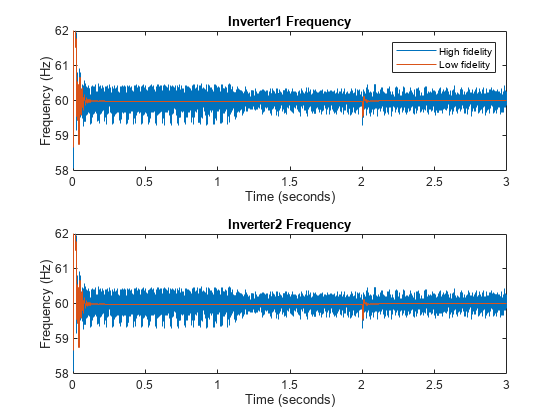

figure;
tiledlayout(2,1)
nexttile
plot(highFidelityLogs{12}.Values)
hold on
plot(lowFidelityLogs{12}.Values)
hold off
ylabel('Frequency (Hz)')
ylim([58 62])
title('Inverter1 Frequency')
legend(["High fidelity", "Low fidelity"])
nexttile
plot(highFidelityLogs{10}.Values)
hold on
plot(lowFidelityLogs{10}.Values)
hold off
ylabel('Frequency (Hz)')
ylim([58 62])
title('Inverter2 Frequency')

Now plot the per-unit voltage of inverters for both models.

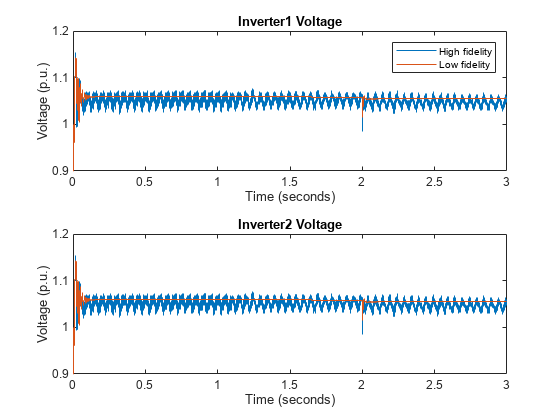

figure;
tiledlayout(2,1)
nexttile
plot(highFidelityLogs{13}.Values)
hold on
plot(lowFidelityLogs{13}.Values)
hold off
ylabel('Voltage (p.u.)')
ylim([0.9 1.2])
title('Inverter1 Voltage')
legend(["High fidelity", "Low fidelity"])
nexttile
plot(highFidelityLogs{11}.Values)
hold on
plot(lowFidelityLogs{11}.Values)
ylabel('Voltage (p.u.)')
ylim([0.9 1.2])
title('Inverter2 Voltage')

As expected, the high-fidelity model captures the frequency and voltage ripple in much more detail, but the low-fidelity model runs much faster.

## **Control Design Considerations**

Regardless of the fidelity level you use, note that there are oscillations in both the frequency and voltage waveforms at each PCC. This result is not surprising as the droop control technique is a simple grid-forming controller for microgrids. Such oscillations might be even worse if you consider the dynamics of energy storage devices and renewable energy resources. To improve the power quality in the microgrid, more advanced approaches are available, such as synchronous machine emulation and virtual oscillator control. You can implement many of these grid-forming controllers based on droop controller architecture.

The inverter controller also contains voltage controllers. You can further tune the voltage PI controllers to achieve better tracking performance of the d-axis and q-axis reference voltages. For an example on how to tune controllers using the [PID Tuner](docid:control_ref#bu3whlk-1) app, see [Design PID Controller Using Simulated I/O Data](docid:slcontrol_ug#mw_5c3201e1-faa4-4b5f-ad4d-c64675b69cca).

## Close Model

Close the model without saving.

close_system(mdl,0)

 *Copyright 2021-2023 The MathWorks, Inc.*